% Load the CSV data
data_truth = readtable('./MH01/data.csv');

data_estimate = readtable('./MH01/output.csv');
timestamp_data_truth = (data_truth{:, 1} - data_truth{1,1});
timestamp_data_estimate = (data_estimate{:, 1} - data_estimate{1,1});

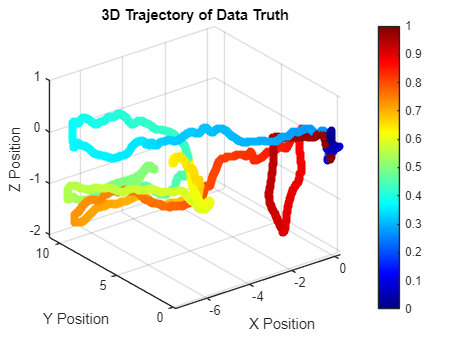

% --------------------- Ground Truth Position Data ------------------- 
% Extract position columns 
x_truth = data_truth.p_RS_R_x_m_; 
y_truth = data_truth.p_RS_R_y_m_; 
z_truth = data_truth.p_RS_R_z_m_; 
% xyz_truth = [x_truth, y_truth, z_truth]';

% Offset positions to start at (0,0,0) 
x_truth = x_truth - x_truth(1); 
y_truth = y_truth - y_truth(1); 
z_truth = z_truth - z_truth(1);

% Normalize timestamps for coloring 
timestamps_norm = (timestamp_data_truth - min(timestamp_data_truth)) / (max(timestamp_data_truth) - min(timestamp_data_truth));

% Plot the 3D trajectory 
figure; 
scatter3(x_truth, y_truth, z_truth, 36, timestamps_norm, 'filled'); 
%scatter3(xyz_truth_map(1, :), xyz_truth_map(2, :), xyz_truth_map(3, :), 36, timestamps_norm, 'filled');
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Trajectory of Data Truth');

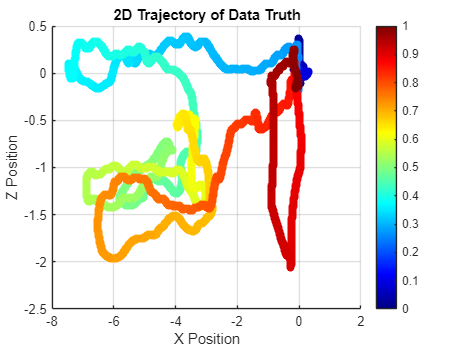

% Plot the XZ for the truth
figure; 
scatter(x_truth, z_truth, 36, timestamps_norm, 'filled'); 
%scatter3(xyz_truth_map(1, :), xyz_truth_map(2, :), xyz_truth_map(3, :), 36, timestamps_norm, 'filled');
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Z Position'); 
title('2D Trajectory of Data Truth');

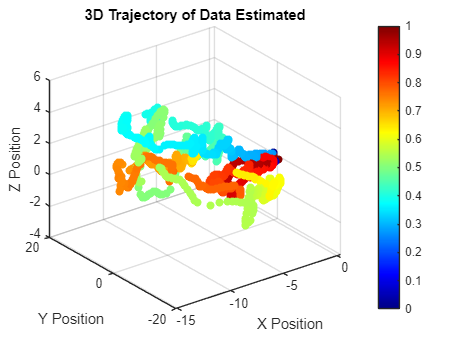

% --------------------- ORB-SLAM3 Pose Estimation Data ------------------- 
% Extract position columns 
x_est = data_estimate.Var4; 
y_est = data_estimate.Var5; 
z_est = data_estimate.Var6; 


% Offset positions to start at (0,0,0) 
x_est = x_est - x_est(1); 
x_est = x_est - x_est(1); 
x_est = x_est - x_est(1);

xyz_est = [x_est, y_est, z_est]';

% Define the rotation matrices 
R_x = [1, 0, 0; 0, 0, -1; 0, 1, 0]; % 90-degree rotation around X-axis 
R_y = [0, 0, 1; 0, 1, 0; -1, 0, 0]; % 90-degree rotation around Y-axis 
R_z = [0, 1, 0; -1, 0, 0; 0, 0, 1]; % 90-degree rotation around Z-axis
R_x_neg = [1, 0, 0; 0, 0, 1; 0, -1, 0]; % 90-degree rotation around X-axis
R_y_neg = [0, 0, -1; 0, 1, 0; 1, 0, 0]; % 90-degree rotation around X-axis
R_180_x = [1, 0, 0; 0, -1, 0; 0, 0, -1]; % 180-degree rotation around X-axis 
R_180_y = [-1, 0, 0; 0, 1, 0; 0, 0, -1];
R_180_z = [-1, 0, 0; 0, -1, 0; 0, 0, 1];
R_45_z = [cos(pi/4), -sin(pi/4), 0; sin(pi/4), cos(pi/4), 0; 0, 0, 1];
% Combined rotation matrix 
R =R_x*R_y;

% Apply the transformation to estimate
xyz_est_map = R * xyz_est;

% Normalize timestamps for coloring 
timestamps_norm_est = (timestamp_data_estimate - min(timestamp_data_estimate)) / (max(timestamp_data_estimate) - min(timestamp_data_estimate));

% Plot the 3D trajectory 
figure; 
%scatter3(x_est, y_est, z_est, 36, timestamps_norm_est, 'filled'); 
scatter3(xyz_est_map(1, :), xyz_est_map(2, :), xyz_est_map(3, :), 36, timestamps_norm_est, 'filled');
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Trajectory of Data Estimated');

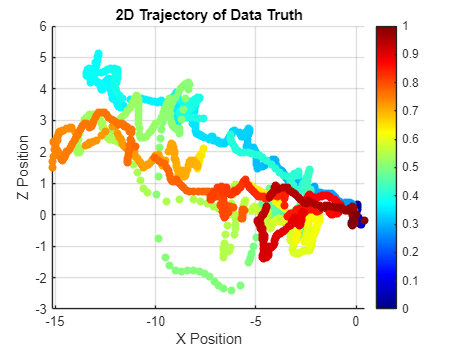

% Plot the XZ for the estimate
figure; 
scatter(xyz_est_map(1, :), xyz_est_map(3, :), 36, timestamps_norm_est, 'filled');
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Z Position'); 
title('2D Trajectory of Data Truth');